# HomeWork n.2 2020/21

**COGNOME: PANICO**

**NOME: GENNARO**

**MATRICOLA: 0124002115**

## Corso di Calcolo Numerico  (CdS Informatica) - prof. G.Giunta, prof. A. Galletti

**(scadenza: 13 Giugno 2021, ore 23:59)**

**UPLOAD DEI DATI**

- **La Relazione ha come primo comando il comando di caricamento dei vostri dati, cioè il comando **`load DatiHW** `** (per caricare la foto e i punti).  Poi procedere come segue.**

Uso il comando **load DatiHWGP** per caricare la foto e i punti, ovvero quelli che saranno i dati da usare nello svolgimento dell'Homework, e inserendo **format long** in primissima sezione, definisco il formato dei risultati per tutta la relazione.

load DatiHW2GP.mat
format long

- ** Visualizzare nella stessa figura la foto dell'oggetto e successivamente i 50 punti  evidenziati con un asterisco rosso sul contorno. Le componenti dei vettori **`x`**  e **`y`**  possono essere scalate, per es. dividendole per 1000, poi devono essere centrate nel baricentro (centroide della figura) e infine devono essere estese aggiungendo in coda un punto fittizio uguale al primo punto, in modo tale che **`x`** e **`y`** siano i vettori delle coordinate dei vertici di un poligono (chiuso).**

Visualizzo la foto dell'oggetto(Transatlantico Andrea Doria) tramite il comando** plot **dandogli: un titolo(**title**); assegnado agli assi le lettere x e y per una maggiore chiarezza(**xlabel - ylabel**), utilizzo anche legend per una maggiore leggibilià e comprensione di ciò che facciamo.

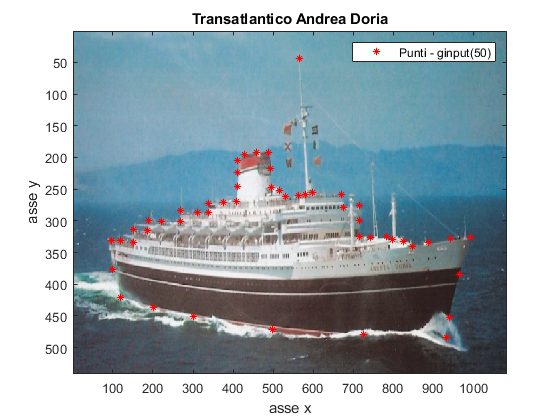

figure(1)
image(A)   %Per mostrare l'immagine 
hold on
title('Transatlantico Andrea Doria')
xlabel('asse x')
ylabel('asse y')
plot((x),(y),'*','markersize', 5, "Color","r")
legend('Punti - ginput(50)') 
hold off

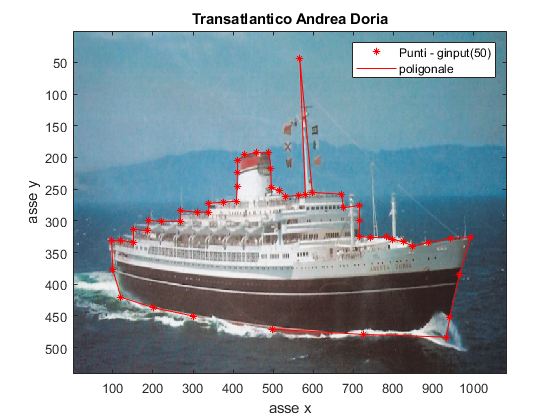

figure(2)
image(A)
hold on 
title('Transatlantico Andrea Doria')
xlabel('asse x')
ylabel('asse y')
plot((x),(y),'*','markersize', 5, "Color","r")
plot(x,y,'r')
legend('Punti - ginput(50)','poligonale') 
hold off

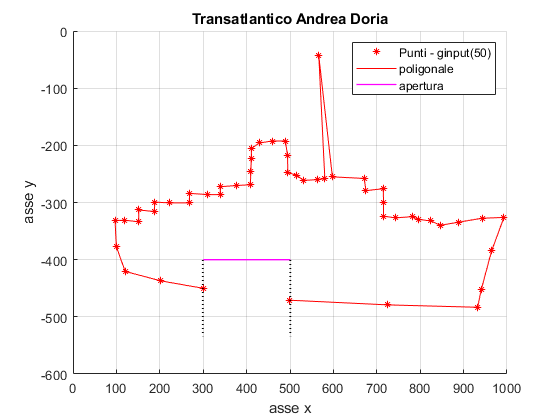

figure(3)

hold on 
grid on
title('Transatlantico Andrea Doria')
xlabel('asse x')
ylabel('asse y')
plot((x),(-y),'*','markersize', 5, "Color","r")
plot(x,-y,'r');
plot([299.99 500.72],[-400 -400],'k','linewidth',1,"Color",'m')    %creo indicativamente una linea per indicare al meglio l'apertura della poligonale
plot([299.22 299.22],[-400 -534], ':b','MarkerSize',5,"LineWidth",1.4,"Color",'k')
plot([500.72 500.72],[-400 -534], ':b','MarkerSize',5,"LineWidth",1.4,"Color",'k')
legend('Punti - ginput(50)', 'poligonale','apertura')
hold off

La poligonale della figura è aperta, per cui dovrò adottare una tecnica per sopperire a questo problema e in un certo senso forzare la chiusura della poligonale. Segue il codice ove viene implementato ciò:

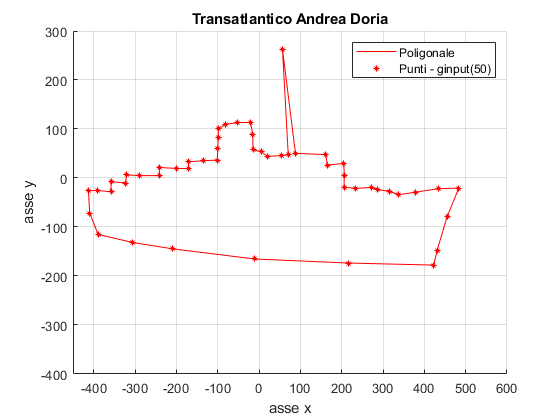

figure(4)


axis on
title('Transatlantico Andrea Doria')
xlabel('asse x')
ylabel('asse y')

xc = mean(x);       %media ascisse tramite function mean()
yc = mean(y);       %media ordinate tramite function mean()
xcentrati = x-xc;   %centratura delle x, sottraggo l'ascissa del centroide al vettore delle ascisse     
ycentrati = -(y-yc);   %centratura delle y, sottraggo l'ordinata del centroide al vettore delle ordinate. Aggiungo anche un segno meno, poiché altrimenti Matlab...
                       %...ruota la mia immagine e perderemmo il senso grafico. 

xcentrati = [xcentrati; xcentrati(1)]; %aggiungo come ultimo punto il primo punto, tramite questo "trucco" forzo la chiusura della poligonale che era aperta
ycentrati = [ycentrati; ycentrati(1)];


hold on
grid on
plot(xcentrati,ycentrati,'r');
plot((xcentrati),(ycentrati),'*','markersize', 4, "Color","r")
axis([-450 600 -400 300])
legend('Poligonale', 'Punti - ginput(50)')
hold off

2.**  Usando i vertici del poligono ottenuti in 1, costruire **`miafotoS`**, cioè la curva parametrica, basata sulle spline cubiche interpolanti, che interpola tali punti. Usare le spline cubiche con derivata prima fissata negli estremi (scegliere un valore appropriato della derivata per entambe le spline). Visualizzare sia il grafico della spline che interpola le ascisse dei punti, sia il grafico della spline che interpola le ordinate dei punti, sia  **`miafotoS `** indicando in blu i punti (per tutti e tre i grafici, usare una griglia fitta di 500 punti).**

Costruisco la grglia fitta passando i **500 pti** come indicato da traccia e utilizzando **t** come parametro della curva parametrica, successivamente è importante notare che nella costruzione delle due spline, ho usato la derivata nulla(0) in quanto la mia immagine, ha quei punti sulla stessa quota, quindi la derivata che mi indica la pendenza, risulta essere approssimativamente nulla avendo la stessa quota.

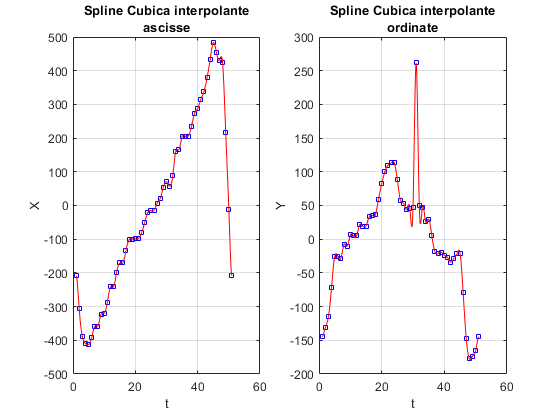

t = 1:length(xcentrati);    % parametro t (sono i nodi dei due problemi classici di interpolazione)
tt = linspace(t(1),t(end),500);    % griglia fitta per la visualizzazione

xspline = spline(t,[0 xcentrati' 0], tt);     %interpolazione delle ascisse, in funzione del parametro t       
yspline = spline(t,[0 ycentrati' 0], tt);     %interpolazione delle ordinate, in funzione del parametro t

figure(5)
subplot(1,2,1)
plot(t,xcentrati,'bs',tt,xspline,'r',"MarkerEdgeColor","b","MarkerSize",4)  %visualizzazione grafica di x(t)
grid on
title({'Spline Cubica interpolante';  'ascisse'})
xlabel('t')
ylabel('X')


subplot(1,2,2)
plot(t,ycentrati,'bs',tt,yspline,'r',"MarkerEdgeColor","b", "MarkerSize",4)    %visualizzazione grafica di y(t)
grid on
title({'Spline Cubica interpolante'; 'ordinate'})
xlabel('t')
ylabel('Y')

Nel grafico a sinistra riporto la spline cubica interpolante  per le ascisse, infatti ciò che sto facendo è creare una funzione X(t) che ottengo appunto andando a interpolare con una spline i punti che hanno ascissa 't' e ordinata 'X' dove X è il vettore che ho chiamato xcentrati.

Analogamente nel grafico a destra faccio più meno la stessa cosa, ma stavolta creo una funzione Y(t) che ottengo andando a interpolare con una spline i punti che hanno ascissa 't' e ordinata 'Y' dove Y è il vettore che ho chiamato ycentrati.

Dai risultati dell'interpolazione sulla griglia fitta, costruisco la curva parametrica formata dai due vettori (xspline, yspline) che hanno 500 elementi ottenuti appunto dalla valutazione sulla griglia fitta **tt **la spline interpolante i 51 punti tx centrati (51 poichè ho chiuso la "poligonale") e i 51 punti ty centrati.

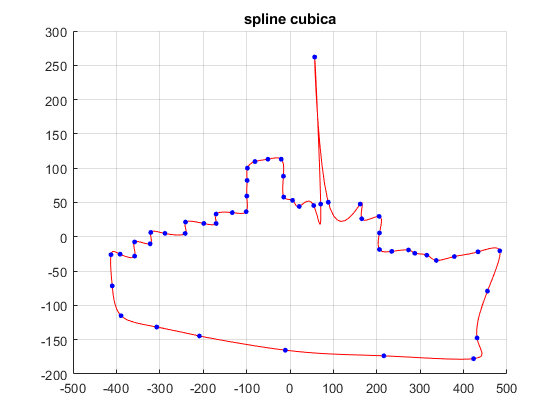

figure(6)
miafotoS = [xspline; yspline];  %matrice di 2 righe e 500 colonne
hold on
grid on
plot(xspline,yspline,'r');
plot(xcentrati,ycentrati,'or','markersize', 3, "MarkerFaceColor","b","MarkerEdgeColor","b")
title('spline cubica')
hold off

3. ** Ripetere tutto quanto richiesto in 2.  per costruire **`miafotoC`**, ovvero la curva parametrica basata sulle cubiche di Hermite. Calcolare la norma infinito del vettore (di 500 componenti) che ha per i-sima componente la distanza tra l' i-simo punto di **`miafotoS `**e l' i-simo punto di **`miafotoC`**.**

Implemento allo stesso modo il punto 3, facendo attenzione peró al fatto che devo utilizzare la **spline cubica di Hermite**, inoltre,** t** e **tt** le ho giá fissate nel punto precedente.

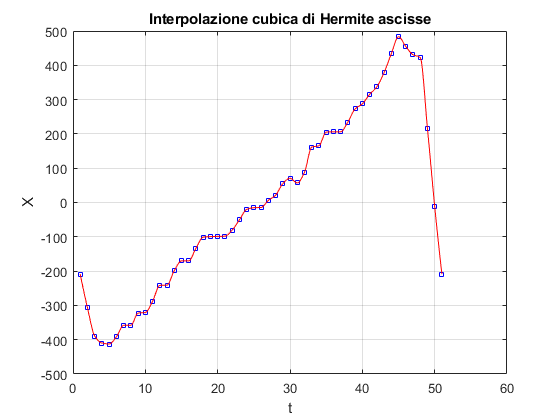

xH = pchip (t, xcentrati, tt);  %interpolazione delle ascisse, in funzione del parametro t  -Hermite
yH = pchip (t,ycentrati,tt);    %interpolazione delle ordinate, in funzione del parametro t    -Hermite
figure(7)
plot(t,xcentrati,'bs',tt,xH,'r',"MarkerEdgeColor","b","MarkerSize",4.5)    %visualizzazione grafica di x(t)
grid on
title('Interpolazione cubica di Hermite ascisse')
xlabel('t')
ylabel('X')

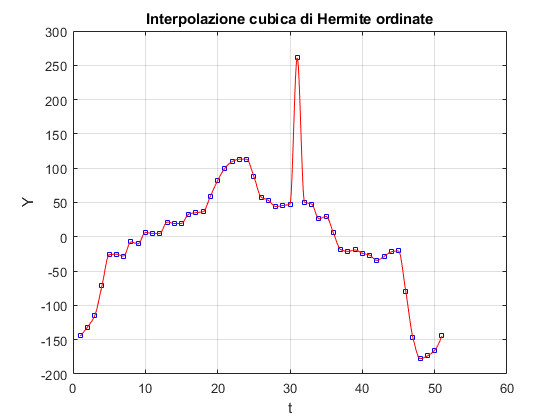

figure(8)
plot(t,ycentrati,'bs',tt,yH,'r',"MarkerEdgeColor","b","MarkerSize",4.5)     %visualizzazione grafica di y(t)
grid on
title('Interpolazione cubica di Hermite ordinate')
xlabel('t')
ylabel('Y')

Con i due vettori *xH* e *yH* costruisco la curva parametrica **miafotoC**

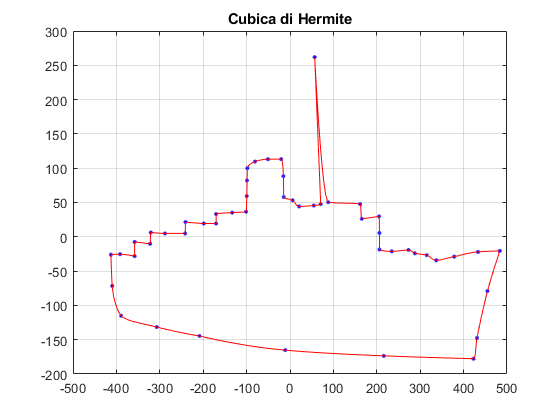

figure(9)
miafotoC = [xH; yH];    %matrice di 2 righe e 500 colonne
plot(xcentrati,ycentrati, '.b', xH, yH, 'r',"MarkerSize",8)    %avrei anche potuto passare miafotoC(:,1) e miafotoC(:,2) anzichè xH e yH
grid on
title('Cubica di Hermite')

Ora procedo al calcolo della distanza tra l'**i-simo punto** della curva parametrica **miafotoS** e l**'i-simo punto** della curva parametrica **miafotoC**: Devo in poche parole individuare e quindi calcolare la distanza massima tra tutte quelle che ci sono, tra le due curve parametriche. Mi calcolo quindi innnanzitutto il vettore delle distanze ed è da notare che uso nel codice, xspline e yspline per miafotoS, xH e yH per miafotoC. Inoltre, la **norma infinito** di un vettore rappresenta il massimo delle componenti del vettore in valore assoluto.

vdistanze = sqrt ( (xspline-xH).^2 + (yspline-yH).^2);  %vettore delle distanze
norm(vdistanze,Inf)

ans =   31.442182668156491


4.  **Considerare il poligono di 500 vertici costituito dai valori della curva parametrica **`miafotoS`**. Visualizzare in rosso tale poligono, usando il comando **`fill`**. Calcolare e visualizzare il perimetro e l'area di questo poligono usando le function **`LunghezzaPoligonale`**  e   **`AreaPoligono`** sviluppate nell'Esercitazione ONLINE8.**

Effettuo il plotting del poligono costituito dai valori della curva parametrica `miafotoS`. 

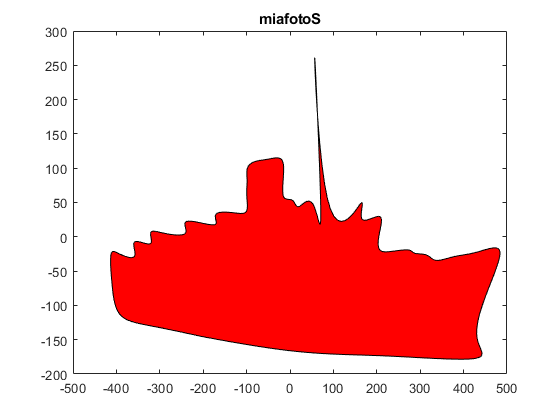

figure(10)
fill(miafotoS(1,:), miafotoS(2,:), 'r')    %riempimento della figura miafotoS
title('miafotoS')

Si noti, inoltre, che miafotoS(1,:) rappresenta *xspline* e miafotoS(2,:) rappresentera *yspline*.

%costrusico le due function pper il calcolo del perimetro e l'area del mio poligono
LunghezzaPoligonale = @(x,y) sum(sqrt(diff(x).^2 + diff(y).^2));
AreaPoligono = @(x,y) 0.5*abs(sum(x(1:end-1).*y(2:end))-sum(y(1:end-1).*x(2:end)));

%applico la fucntion LunghezzaPoligonale per calcolare il perimetro, le passo il vettore delle...
%...ascisse e il vettore delle ordinate di miafotoS
PerimetroS = LunghezzaPoligonale(miafotoS(:,1), miafotoS(:,2))

PerimetroS =   92.075313904852365


%applico la function AreaPoligono oper calcolare l'area
AreaS = AreaPoligono(miafotoS(:,1), miafotoS(:,2))  

AreaS =      1.424056273282349e+02


5. ** Ripetere tutto quanto richiesto in 4. per la curva parametrica **`miafotoC`**. Calcolare e visualizzare la differenza tra il perimetro di **`miafotoS e miafotoC`**   e la differenza tra l'area di  **`miafotoS`**  e  **`miafotoC.`

`Implemento allo stesso modo il plotting e il riempimento di miafotoC, facendo attenzione unicamente ai parametri passati che devono essere per l'appunto: `miafotoC(1,:) che rappresenta *xH*  e miafotoS(2,:) che rappresenta *yH*.

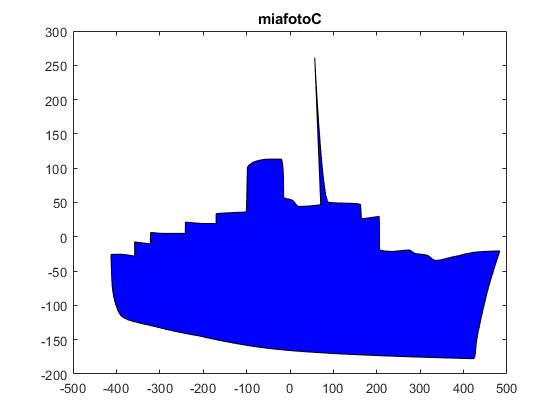

figure(11)
fill(miafotoC(1,:), miafotoC(2,:), 'b')    %riempimento della figura miafotoC
title('miafotoC')

AreaC = AreaPoligono(miafotoC(:,1), miafotoC(:,2))  %ripeto per miafotoC il calcolo dell'area

AreaC =      8.854092004530758e+02


PerimetroC = LunghezzaPoligonale(miafotoC(:,1), miafotoC(:,2))    %ripeto per miafotoC il calcolo del perimetro

PerimetroC =   99.387873717150299


Volendo, sia per AreaC che per PerimetroC avrei potuto passare **xH** e **yH** anziché **miafotoC(:,1)** e **miafotoC(:,2)**.

Diff_perimetro = PerimetroS-PerimetroC   %Calcolo la differenza di perimetro tra miafotoSe miafotoC

Diff_perimetro =   -7.312559812297934


Diff_aree = AreaS-AreaC   %Calcolo la differenza di aree tra miafotoSe miafotoC

Diff_aree =     -7.430035731248408e+02


6.**  Costruire la matrice **`D`** delle distanze dei 51 punti  ottenuti al termine della domanda 1. cioè la matrice quadrata di ordine 51 il cui elemento **`(i,j)`** è la distanza tra  il punto **`i`** e il punto **`j`** . Visualizzare il blocco di **`D`** che coinvolge le distanze tra i primi 8 punti.**

I **51** punti devono essere i punti che caratterizzano i vertici del poligono. Procedo quindi alla sua costruzione elemento per elemento, con un **doppio ciclo for**. Presto attenzione al fatto che la matrice delle distanze è una **matrice simmetrica **quindi è inutile che mi costruisco la parte sottostante alla diagonale principale della matrice, inoltre la distanza di un punto a se stesso è **0** per tanto la mia diagonale principale avrà appunto tutti i valori pari a **0**. Proprio per questo  motivo la matrice **D** viene costruita con un for interno che parte da **i+1** per arrivare fino a **end**, quindi **non da 1 a 51, ma da i+1 a 51** per le proprietà strutturali della **matrice delle distanze**. Implemento poi quella che è la sintassi che definisce la mia **D(i,j)**, facendo: disanza(**sqrt**) del punto **i** e del punto **j**; **xcentrati** e **ycentrati** sono i punti che avevo selezionato precedentemente con la ginput, ma dopo l'operazione di centratura rispetto al **centroide. **

D=zeros(50,51);    %Dichiaro D
for i = 1:51 
    for j = i+1:51
        D(i,j) = sqrt((xcentrati(j)-xcentrati(i)).^2 + ((ycentrati(j)-ycentrati(i)).^2));
    end
end
D1 = D(1:8,1:8)    %visualizzo il blocco 1:8, 1:8 della matrice D

D1 = 	1.0e+02 *

                   0   0.991247238907936   1.829165037970971   2.137498860971469   2.357576156970923   2.181473531388459   1.892802119962423   2.026586664539606
                   0                   0   0.838906633120429   1.188546759694599   1.491836958135173   1.356174521038946   1.152484759513189   1.341055387100943
                   0                   0                   0   0.479626239828326   0.919032936193864   0.896189595357569   0.923032838523306   1.119733940651723
                   0                   0                   0                   0   0.455784236776176   0.496302838703022   0.674941156108667   0.823301835967732
                   0                   0                   0                   0                   0   0.211181031154038   0.546258339491465   0.576710629534079
                   0                   0                   0                   0                   0                   0   0.335931381117258   0.379732960789774
                 

7.  **Usando la matrice delle distanze **`D`** ricavata in 6., determinare la distanza tra i due punti più lontani del bordo dell'oggetto (ovvero il diametro della nube di punti), visualizzare tale distanza e visualizzare una figura con il contorno dell'oggetto e il segmento (in rosso) che unisce i due punti più lontani.**

Possiamo determinare tale distanza tra due punit in piú modi, ma la soluzione che adotto in questo caso é la visualizzazione della matrice D come un unico vettore nel quale tutte le colonne sono poste una sotto l'altra (tale vettore prende il nome di **D stacked**), e di tale vettore ne individuiamo il valore e l'indice del massimo (dove il massimo rappresenta la distanza tra i due punti più lontani del bordo dell'oggetto).

[max_val, pos_idx] = max(D(:))  %Ottenimento del valore massimo e il suo indice

max_val =      8.959665603539619e+02


pos_idx =         2205


Dopo aver ottenuto il valore massimo e il suo indice, uso il comando ind2sub per risalire da pos_idx(del vettore D stacked) alla corrispondente coppia di indice nella matrice D.

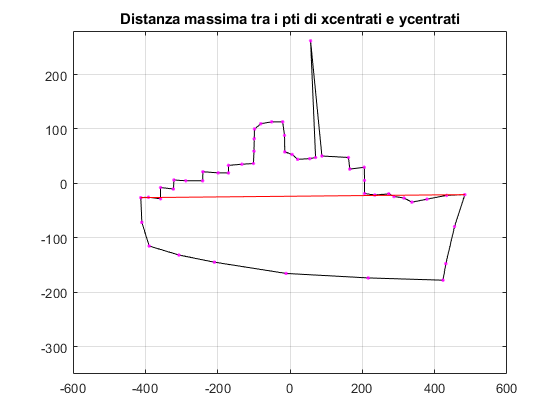

[i,j] = ind2sub(size(D),pos_idx);   %ricava le coordinate i-sima e j-sima di D

figure(12)
plot(xcentrati,ycentrati,'k');
axis on 
axis([-600 600 -350 280])
hold on
grid on
plot(xcentrati,ycentrati,'.m',"LineWidth",6)
plot([xcentrati(j) xcentrati(i)], [ycentrati(j) ycentrati(i)], 'r')    %plotting della retta che congiunge i due punti con distanza max.
title('Distanza massima tra i pti di xcentrati e ycentrati')

La lunghezza edl segmento in rosso risulta essere il **diametro** della "nube" di punti in viola.

8.  **Fissare un angolo **`teta`** a caso (usare opportunamente **`rand`**) tra 10 e 80 gradi e fare ruotare in verso orario **`miafotoS `**di tale  angolo e in verso antiorario **`miafotoC`**. Visualizzare nella stessa figura  **`miafotoS `**e **`miafotoS `**ruotata  e poi in un'altra figura  **`miafotoC `** e  **`miafotoC `**ruotata.**

Procedo con l'implementazione Matlab fissando innanzitutto il mio angolo teta che come indicato dalla traccia deve essere compreso tra i 10 e gli 80 gradi. Partendo dal presupposto che una rotazione in Matlab viene eseguita ruotando tutti i vertici della figura, fissando teta, non mi resta poi che definre la matrice di rotazione **R** e essendo in gradi ho bisogno di utilizzare **cosd** e **sind** perché altrimenti MatLab li considera in radianti. Fatto ció, la matrice **R** cosí definita mi crea il **senso orario** e la **R'** mi crea il **senso antiorario**.

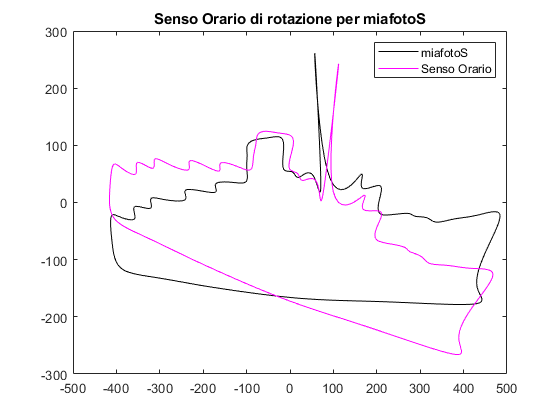

teta = 10+rand(1,1)*(80-10);
R = [cosd(teta), sind(teta); -sind(teta), cosd(teta)];    %definisco la rotazione passando l'angolo randomico compreso tra 10 e 80 gradi

%implemento il verso di rotazione, orario per miafotoS e antiorario per miafotoC
S_Orario = R*miafotoS;
S_AntiOrario = R'*miafotoC;

%plotting per miafotoS
figure(13)
plot(miafotoS(1,:), miafotoS(2,:), 'k');
hold on
plot(S_Orario(1,:), S_Orario(2,:), 'm');
title('Senso Orario di rotazione per miafotoS')
legend('miafotoS', 'Senso Orario')
hold off

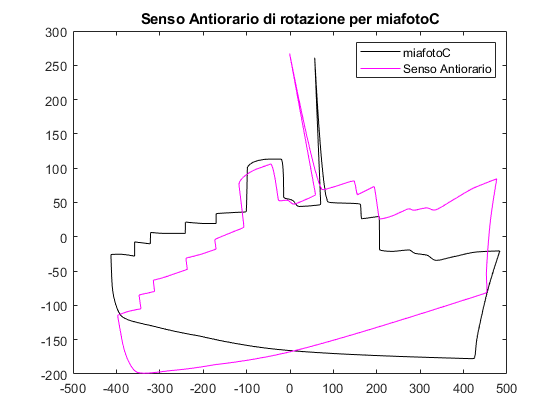

%plotting per miafotoC
figure(14)
plot(miafotoC(1,:), miafotoC(2,:), 'k');
hold on
plot(S_AntiOrario(1,:), S_AntiOrario(2,:), 'm');
title('Senso Antiorario di rotazione per miafotoC')
legend('miafotoC', 'Senso Antiorario')
hold off

9.  **Usando i vertici del poligono ottenuti in 1, costruire **`miafotoAppr5`**, cioè la curva parametrica, basata sull'approssimazione nel senso dei minimi quadrati con polinomi di grado 5., ottenuta approssimando separatamente le ascisse e le ordinate di tali punti. Visualizzare sia il grafico del polinomio che approssima nel senso MQ le ascisse dei punti, sia il grafico del polinomio che approssima nel senso MQ  le ordinate dei punti, sia **`miafotoAppr5`**, indicando in blu i punti (per tutti e tre i grafici, usare una griglia fitta di 500 punti).**

Innanzitutto uso **polyfit** passandole i dati utilizzati per il punto 1 e specificando il grado(5) del polinomio che voglio costruire, successivamente effettuo una valutazione tramite la function **polyval** proprio sul polinomio e le passo anche **tt**, che nel punto 1 ho definito come griglia fitta di 500 punti. Successivamente eseguo il plot prendendo in considerazione l'interpolazione con la cubica di Hermite, in questo modo mostro quanto l'approssimazione con solo grado 5, risulta essere meno precisa rispetto all'interpolazione con la cubica di Hermite. Eseguo tale implementazione, sia per le ascisse che per le ordinate.

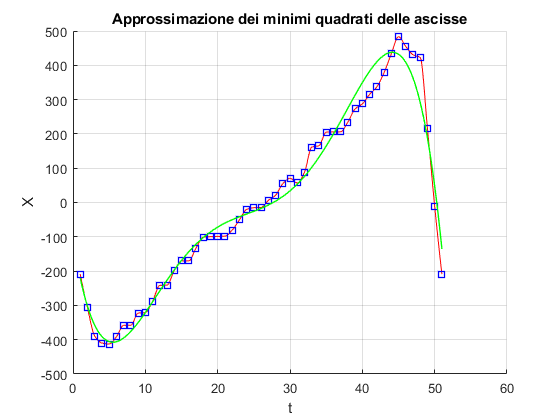

%uso polyfit per costruire il polinomio di grado 5
pfit_x = polyfit(t,xcentrati,5);
pfit_y = polyfit(t,ycentrati,5);



%uso polyval per valutare il polinomio sui 500 punti 
pvalxMQ = polyval(pfit_x,tt);
pvalyMQ = polyval(pfit_y,tt);

%plotting per le ascisse
figure(15)
hold on
title('Approssimazione dei minimi quadrati delle ascisse')
plot(tt,xH,"LineWidth",0.1,"Color",'r');
plot(t,xcentrati,'bs', tt,pvalxMQ,'g','LineW',1)
grid on
xlabel('t')
ylabel('X')
hold off

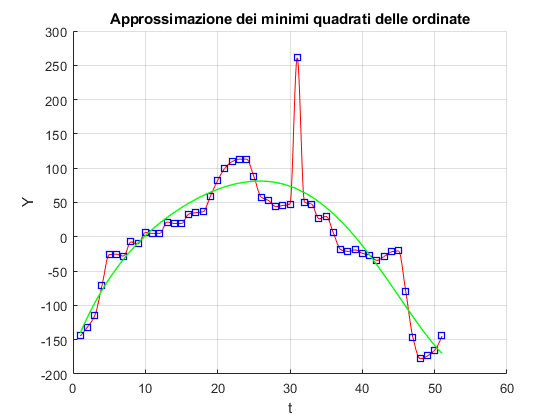

%plotting per le ordinate
figure(16)
hold on
title('Approssimazione dei minimi quadrati delle ordinate')
plot(tt,yH,"LineWidth",0.1,"Color",'r');
plot(t,ycentrati,'bs', tt,pvalyMQ,'g','LineW',1)
grid on
xlabel('t')
ylabel('Y')
hold off

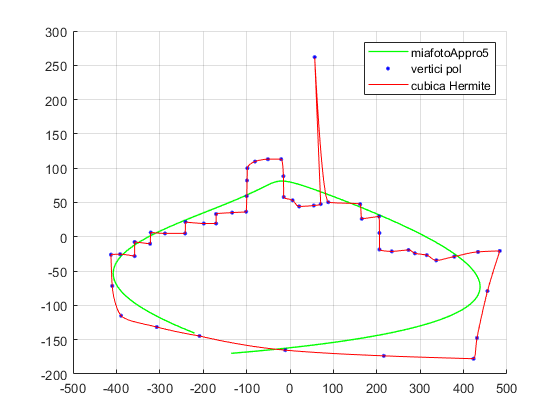

miafotoAppr5 = [pvalxMQ;   pvalyMQ];    %curva parametrica basata sull'approssimazione nel senso dei minimi quadrati con polinomi di grado 5

%plotting dimostrativo
figure(17)
hold on
plot(pvalxMQ,pvalyMQ,"LineWidth",1, "Color",'g')
plot(xcentrati,ycentrati, '.b', xH, yH, 'r',"MarkerSize",8)    
grid on
legend('miafotoAppro5', 'vertici pol','cubica Hermite')
hold off

Nella figura finale ho scelto come grafico di paragone, la **cubica di Hermite** che sembra essere quella che meglio delinea il contorno della mia immagine, e noto che la curva parametrica per approssimazione dei MQ con polinomio di grado 5, risulta essere inesatta rispetto a quella che è la mia immagine, la mia immagine è denotata da numerosi spigoli e quindi dettagli che un' approssimazione di grado 5 non può mostrarmi.